# CONTROLLO AVANZATO E APPLICAZIONI __ ESAME DEL 27/04/2026__________SALVATORE ___ RAIOLA ___ DE6000008

clear; close all; clc;

### 0) DEFINIZIONI

Variabili simboliche 


        syms x1 x2 theta dx1 dx2 dtheta ddx1 ddx2 ddtheta u1 u2 real

Parametri


        m1 = 1.5;
        m2 = 1.0;
        mp = 0.25;
        l = 0.40;
        J = 0.013;
        k = 35;
        b = 4;
        g = 9.81;

Ingresso, Stato e Uscita


        u = [u1;
             u2];

        x = [x1;
             x2;
             theta;
             dx1;
             dx2;
             dtheta];

        y = [x1;
             x2;
             theta];

Modello Dinamico non lineare


        eq1 = (m1+mp)*ddx1 + mp*l*cos(theta)*ddtheta - mp*l*sin(theta)*dtheta^2 + k*(x1-x2) + b*(dx1-dx2) == u1;
        eq2 = m2*ddx2 + k*(x2-x1) +b*(dx2-dx1) == u2;
        eq3 = (J+mp*l^2)*ddtheta + mp*l*cos(theta)*ddx1 - mp*g*l*sin(theta) == 0;

        eqs = [eq1;
               eq2;
               eq3];

        sol = solve(eqs, [ddx1, ddx2, ddtheta]); 

        dx_sym = [dx1;
                  dx2;
                  dtheta;
                  sol.ddx1;
                  sol.ddx2;
                  sol.ddtheta];

        eq_ddx1_sym = sol.ddx1;
        eq_ddx2_sym = sol.ddx2;
        eq_ddtheta_sym = sol.ddtheta;

        f = dx_sym;

## 1. PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### 1.1) Punti di equilibrio del sistema 


        eq_ddx1 = subs(eq_ddx1_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;
        eq_ddx2 = subs(eq_ddx2_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;
        eq_ddtheta = subs(eq_ddtheta_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;
        
        % Fissiamo x1 = 0 per eliminare la traslazione libera e trovare x2 e theta
        sol_peql = solve([eq_ddx1, eq_ddx2, eq_ddtheta, x1 == 0], [x1, x2, theta], 'ReturnConditions',true);

        x1_bar = sol_peql.x1;
        x2_bar = sol_peql.x2;
        theta_bar = sol_peql.theta;
        dx1_bar = 0;
        dx2_bar = 0;
        dtheta_bar = 0;

        disp('1.1) Punti di equilibrio del sistema\n\n'); 

1.1) Punti di equilibrio del sistema\n\n



        disp(table(x1_bar, x2_bar, theta_bar, dx1_bar, dx2_bar, dtheta_bar));

    x1_bar    x2_bar    theta_bar    dx1_bar    dx2_bar    dtheta_bar
    ______    ______    _________    _______    _______    __________

      0         0         pi*k          0          0           0     



#### 1.2) Sistema linearizzato nel punto di lavoro con x=0 e u=0


        x_star = [0;
                  0;
                  0;
                  0;
                  0;
                  0];
        
        u_star = [0;
                  0];

        A_sym = jacobian(f, x);
        
        disp('Matrice A (simbolica):');

Matrice A (simbolica):


        A_sym

$$A\_sym = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ \frac{7420}{\sigma_{3}} & -\frac{7420}{\sigma_{3}} & -\frac{2\,\left(53\,{\mathrm{dtheta}}^{2}\,\cos\left(\theta \right)-981\,{\cos\left(\theta \right)}^{2}+981\,{\sin\left(\theta \right)}^{2}\right)}{5\,\sigma_{3}}-\frac{32\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(53\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-2120\,{\mathrm{dx}}_{1}+2120\,{\mathrm{dx}}_{2}+530\,u_{1}-18550\,x_{1}+18550\,x_{2}-981\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{{\sigma_{3}}^{2}} & \frac{848}{\sigma_{3}} & -\frac{848}{\sigma_{3}} & -\frac{212\,\mathrm{dtheta}\,\sin\left(\theta \right)}{5\,\sigma_{3}}\\ 35 & -35 & 0 & 4 & -4 & 0\\ -\sigma_{1} & \sigma_{1} & \frac{80\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(40\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-6867\,\sin\left(\theta \right)-1600\,{\mathrm{dx}}_{1}\,\cos\left(\theta \right)+1600\,{\mathrm{dx}}_{2}\,\cos\left(\theta \right)+400\,u_{1}\,\cos\left(\theta \right)-14000\,x_{1}\,\cos\left(\theta \right)+14000\,x_{2}\,\cos\left(\theta \right)\right)}{{\sigma_{3}}^{2}}-\frac{6867\,\cos\left(\theta \right)-40\,{\mathrm{dtheta}}^{2}\,{\cos\left(\theta \right)}^{2}+40\,{\mathrm{dtheta}}^{2}\,{\sin\left(\theta \right)}^{2}-1600\,{\mathrm{dx}}_{1}\,\sin\left(\theta \right)+1600\,{\mathrm{dx}}_{2}\,\sin\left(\theta \right)+400\,u_{1}\,\sin\left(\theta \right)-14000\,x_{1}\,\sin\left(\theta \right)+14000\,x_{2}\,\sin\left(\theta \right)}{\sigma_{3}} & -\sigma_{2} & \sigma_{2} & \frac{80\,\mathrm{dtheta}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{14000\,\cos\left(\theta \right)}{\sigma_{3}}\\ \sigma_{2}=\frac{1600\,\cos\left(\theta \right)}{\sigma_{3}}\\ \sigma_{3}=40\,{\cos\left(\theta \right)}^{2}-371 \end{array}$$


        B_sym = jacobian(f, u);
        disp('Matrice B (simbolica):');

Matrice B (simbolica):


        B_sym

$$B\_sym = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ -\frac{212}{40\,{\cos\left(\theta \right)}^{2}-371} & 0\\ 0 & 1\\ \frac{400\,\cos\left(\theta \right)}{40\,{\cos\left(\theta \right)}^{2}-371} & 0 \end{array}\right)$$


        A = double(subs(A_sym, [x; u], [x_star; u_star]));
        B = double(subs(B_sym, [x; u], [x_star; u_star]));
        
        n = size(A, 1);
        m = size(B, 2);

        C = eye(n);

        D = zeros(n, m);

        poles = eig(A);
        
        
        disp('1.2) Sistema linearizzato attorno al punto di lavoro corrispondente a x=0 e u=0\n\n');

1.2) Sistema linearizzato attorno al punto di lavoro corrispondente a x=0 e u=0\n\n


        A

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
  -22.4169   22.4169   -1.1855   -2.5619    2.5619         0
   35.0000  -35.0000         0    4.0000   -4.0000         0
   42.2961  -42.2961   20.7462    4.8338   -4.8338         0


        B

B =          0         0
         0         0
         0         0
    0.6405         0
         0    1.0000
   -1.2085         0


        C

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


        D

D =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0



        disp('Autovalori A: ');  disp(poles);

Autovalori A: 
  -3.2696 + 6.7801i
  -3.2696 - 6.7801i
  -4.4989 + 0.0000i
   4.4762 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i



#### 1.3) Verifica controllabilità e Osservabilità


        disp('1.3) Verifica controllabilità e Osservabilità');

1.3) Verifica controllabilità e Osservabilità



        if rank(ctrb(A, B)) == n
            fprintf(' Il Sistema lineaarizzato è completamente controllabile');
        else
            fprintf('  Il Sistema lineaarizzato NON è completamente controllabile');
        end

 Il Sistema lineaarizzato è completamente controllabile


        %

        if rank(obsv(A, C)) == n
            fprintf(' Il Sistema lineaarizzato è completamente osservabile');
        else
            fprintf('  Il Sistema lineaarizzato NON è completamente osservabile');
        end  

 Il Sistema lineaarizzato è completamente osservabile

## 2. APPROCCIO ALLA LYAPUNOV

#### 2.1) Risoluzione LMI

        
        cvx_clear;
        cvx_begin sdp quiet
            cvx_precision high
    
            variable Q(n,n) symmetric
            variable L(m,n)
    
            minimize(0)
    
            subject to
                Q >= 1e-6*eye(n);
                A*Q + Q*A' + B*L + L'*B' <= -1e-6*eye(n);
        cvx_end
        
        % 

        if ~(strcmp(cvx_status, 'Solved'))
            disp('CVX non ha trovato soluzione per: '); disp(cvx_status);
        end
    
        Qval = Q;
        Lval = L;
    
        K_LMI = L/Q;
    
       
        K_LMI

K_LMI =    28.8714  -27.2652   53.3944   10.6014   -4.9271   10.6149
    1.9301   -1.4058   25.8405    4.0715   -1.5117    5.9802


#### 2.2) Verifica MATLAB


        Acl_LMI = A+B*K_LMI;

        poles_cl_LMI = eig(Acl_LMI);


        Autovalori a ciclo chiuso:

        disp(poles_cl_LMI);

  -2.5363 + 6.2060i
  -2.5363 - 6.2060i
  -3.2322 + 3.3084i
  -3.2322 - 3.3084i
  -0.3460 + 0.0000i
  -2.2283 + 0.0000i



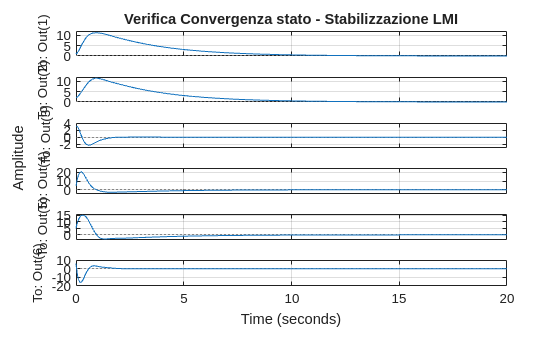


        sys_cl_LMI = ss(Acl_LMI, B, C, D);
        
        % supponiamo uno stato iniziale diverso da 0
        x0_LMI = [1;
                  2;
                  3;
                  4;
                  5;
                  6];
       
        figure;
        initial(sys_cl_LMI, x0_LMI);
        grid on;
        title('Verifica Convergenza stato - Stabilizzazione LMI');

## 3. ASSEGNAMENTO DEGLI AUTOVALORI

Autovalori desiderati per avere tempo di assestamento < 10s


        eig_des = [-1.5, -1.6, -1.7, -1.8, -1.9, -2.0];

Condizioni iniziali


        x0_EIG = [0.05;
                  -0.05;
                  10;
                  0;
                  0;
                  0];

Valori di riferimento costante


        xref_EIG = [0.15;
                    0.15];

#### 3.1) Guadagno del controllore 


        K_EIG = place(A, B, eig_des);
        K_EIG

K_EIG =   -35.7788   34.9995  -32.7742   -5.7968    3.9997   -6.7527
   48.6237  -31.9695  140.9132   27.6670   -0.5096   38.0632


#### 3.2) Parametri per la simulazione 


        C_inseguimento_EIG = [1, 0, 0, 0, 0, 0;
                              0, 1, 0, 0, 0, 0];

Compensazione

        N = inv(C_inseguimento_EIG*(-inv(A-B*K_EIG))*B);
        
        %
        disp('Compensazione:'); 

Compensazione:


        N        

N =    -0.7788   -0.0005
   13.6237    3.0305


#### Verificare il risultato aprendo il file Simulink: [VerificaAssegnamentoAutovalori_27042026.slx](matlab:open_system('VerificaAssegnamentoAutovalori_27042026.slx'))

## 4. CONTROLLO LQR CON AZIONE INTEGRALE

#### 4.1) Sistema Aumentato

        x1_ref_lqr = 1;
        x2_ref_lqr = 2;

        x_ref_lqr = [x1_ref_lqr;
                     x2_ref_lqr];

        x0_LQR = [0.1;
                  1.1;
                  3;
                  4;
                  5;
                  6];

        x_a = [x1;
               x2;
               theta;
               dx1;
               dx2;
               dtheta;
               x1-x1_ref_lqr;
               x2-x2_ref_lqr];

        C_LQR = C_inseguimento_EIG;
    
        A_a = [A      , zeros(6,2);
               - C_LQR, zeros(2,2)];
    
        B_a = [B;
               zeros(2,2)];

        C_a = eye(8);
    
        D_a = zeros(8,2);
        A_a

A_a =          0         0         0    1.0000         0         0         0         0
         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000         0         0
  -22.4169   22.4169   -1.1855   -2.5619    2.5619         0         0         0
   35.0000  -35.0000         0    4.0000   -4.0000         0         0         0
   42.2961  -42.2961   20.7462    4.8338   -4.8338         0         0         0
   -1.0000         0         0         0         0         0         0         0
         0   -1.0000         0         0         0         0         0         0


        B_a

B_a =          0         0
         0         0
         0         0
    0.6405         0
         0    1.0000
   -1.2085         0
         0         0
         0         0


        C_a

C_a =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


        D_a

D_a =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


#### 4.2) Sintesi LQR con Tempo di Assestamento specificato


        Ts = 5;

        alpha = 4/Ts;

        A_a_hat = A_a + alpha*eye(size(A_a));

        q_i_stato = 1;
        q_1_integrali = 100;

        Q_a = diag([q_i_stato, q_i_stato, q_i_stato, q_i_stato, q_i_stato, q_i_stato, q_1_integrali, q_1_integrali]);
        Q_a

Q_a =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0   100     0
     0     0     0     0     0     0     0   100



        R_a = 1*eye(2);
        R_a

R_a =      1     0
     0     1


        %
        [K_LQR, P, e_bar] = lqr(A_a_hat, B_a, Q_a, R_a);

        K_LQR

K_LQR =   -93.9699   35.9455 -144.2410  -41.7922    6.2275  -33.1415   36.8011    6.5746
  -39.1248   29.3052  -58.6186  -15.6929    5.7938  -13.4704   86.3279  -82.9289


Verifica 


        A_cl_LQR = A_a - B_a*K_LQR;

        poles_cl_LQR = eig(A_cl_LQR);

        Poli a ciclo chiuso:

        
        disp(poles_cl_LQR);

  -3.3317 + 6.7581i
  -3.3317 - 6.7581i
  -6.2524 + 0.0000i
  -4.3931 + 0.0000i
  -1.8977 + 1.4952i
  -1.8977 - 1.4952i
  -2.9198 + 0.0000i
  -1.6145 + 0.0000i



Guadagni

        
        K_LQR_x = K_LQR(:, 1:n);       % Prende tutte le righe, colonne da 1 a 3
        K_LQR_x

K_LQR_x =   -93.9699   35.9455 -144.2410  -41.7922    6.2275  -33.1415
  -39.1248   29.3052  -58.6186  -15.6929    5.7938  -13.4704


        K_LQR_i = K_LQR(:, n+1:end);   % Prende tutte le righe, colonne da 4 a 5         
        K_LQR_i

K_LQR_i =    36.8011    6.5746
   86.3279  -82.9289


#### Verificare il risultato aprendo il file Simulink: [VerificaLQR_27042026.slx](matlab:open_system('VerificaLQR_27042026'))

## 5. CONTROLLO LQG

#### 5.1) Definizioni    

Matrici di covarianza

        Q_cov = 1e-4*eye(n);
        R_cov = 1e-3*eye(3);
        xref_LQG = [x_ref_lqr;
                    3];

Matrice C

        C_LQG = [1, 0, 0, 0, 0, 0;
                 0, 1, 0, 0, 0, 0;
                 0, 0, 1, 0, 0, 0];

Guadagno di Kalman

        [P_kal, ~, ~] = care(A', C_LQG', Q_cov, R_cov);
        L = P_kal*C_LQG'/R_cov;
A_kf = A-L*C_LQG;
B_kf = [B, L];
C_kf = eye(n);  